%syms mc mp x dx l th dth g F Fcart Fpend ddx ddth s Fdist b
mc=0.9+0.1; 
mp=0.08887;
l= 0.36022;
g = 9.82;

% Without Disturbance linear
E = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fpend];
S = solve(E,ddx,ddth);
S.ddx;
S.ddth;

% With Disturbance linaer
E1 = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fdist-Fpend];
S1 = solve(E1,ddx,ddth);
S1.ddx;
S1.ddth;

% Nonlinear
E2 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-Fcart, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -Fpend];
S2 = solve(E2, ddx, ddth);
S2.ddx;
S2.ddth;

% Fpend and Fcart are b * x/th
E3 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-b*dx, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -b*dth];
S3 = solve(E3, ddx, ddth);
S3.ddx;
S3.ddth;

% State space model

C1 = [0 0 1 0;
      1 0 0 0];
s = tf('s'); 
S = [s 0 0 0;
     0 s 0 0;
     0 0 s 0;
     0 0 0 s];
  
A = [0 1 0 0;
     0 0 0 1;
     0 (-g*mp)/(mc+2*mp) 0 0;
     0 -(g*(mp+mc))/(l*(mc+2*mp)) 0 0];
  
B = [0 0;
     0 0;
     1/(mc+2*mp) 1/(l*(mc+2*mp));
     -1/(l*(mc+2*mp)) -(mc+mp)/(l^2*mp*(mc+2*mp))];

u = [F-Fcart; -Fpend];
 
system = ss(A,B,C,0)

system =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -0.741       0
   x3       0       0       0       1
   x4       0       0   -25.2       0
 
  B = 
           u1      u2
   x1       0       0
   x2  0.8491   2.357
   x3       0       0
   x4  -2.357  -80.17
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
   y2   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.





observability = obsv(system);
rank(observability); % Full rank

controlability = ctrb(system);
rank(controlability); % Full rank






[Gnum,Gden] = ss2tf(A,B,C,[0 0; 0 0], 1);
SS2TF1 = Gnum(1,:)

SS2TF1 =          0         0   -2.3571         0         0


SS2TF2 = Gnum(2,:)

SS2TF2 =          0         0    0.8491         0   23.1470


 
G1 =tf(SS2TF1, Gden)

G1 =
 
    -2.357 s^2
  --------------
  s^4 + 25.2 s^2
 
Continuous-time transfer function.



G2 =tf(SS2TF2, Gden)

G2 =
 
  0.8491 s^2 + 23.15
  ------------------
    s^4 + 25.2 s^2
 
Continuous-time transfer function.



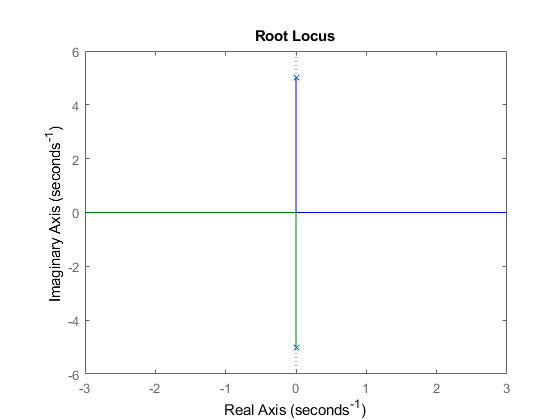

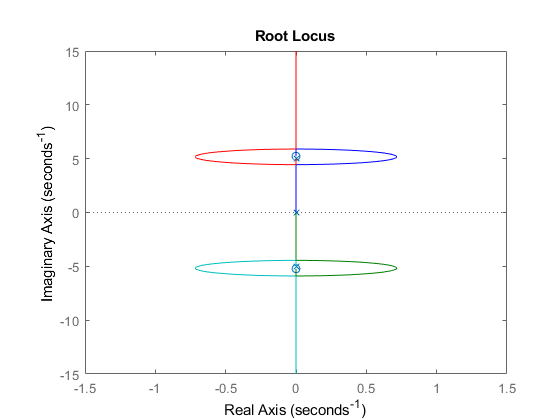

 
rlocus(G1)

rlocus(G2)
% It uses rational numbers instead of decimals.
%  G = C*inv((s-A))*B*u
%  simplify(G);



 
 
 
 
 
 
 
 
 
 
 
 
 
G1_F_Fcarts2 =2653887665070669/(8*140737488355328);
G1_F_Fcart =2653887665070669/3547154207439901;
1/0.7482;
G1_Fpends2 = 11283545366649974/140737488355328;
G1_Fpend = 11283545366649974/3547154207439901;


G2_F_Fcarts4 = 17712895018885581267408060950451/(72057594037927936*140737488355328);
G2_F_Fcarts2 = 17712895018885581267408060950451/(72057594037927936*3547154207439901);
1/0.0693;
G2_F_Fcart = 50000/58887;
1/0.8491;
G2_Fpends4 = 37654995188913115226200270968773/(4503599627370496*140737488355328);
G2_Fpends2 = 37654995188913115226200270968773/(4503599627370496*3547154207439901);
G2_Fpend = 2653887665070669/1125899906842624;